# **纳米线实验数据**

### **读入图片并重构**

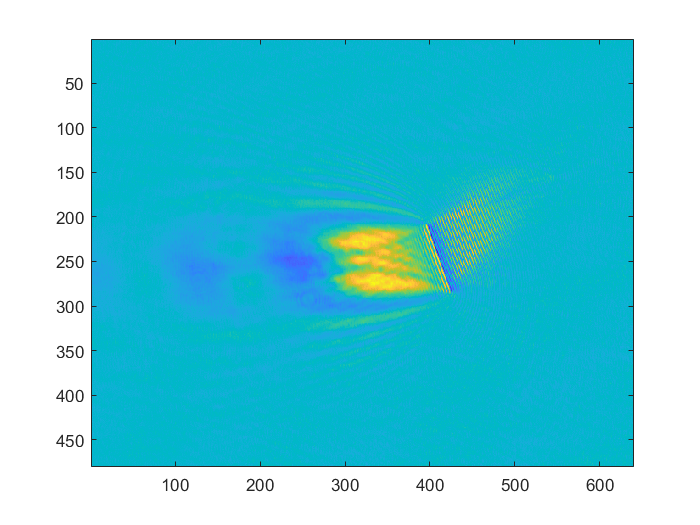

clear
filepath = 'D:\work\散射场\实验数据\20220315_60nmAuNPs_AgNWs\20220315_AgNWs_25fps\A1';
tiffs = dir(fullfile(filepath,'*.*tif*'));
BG = double(imread(fullfile(filepath,tiffs(43).name)));
I = double(imread(fullfile(filepath,tiffs(42).name))) - BG;
figure
imagesc(I)

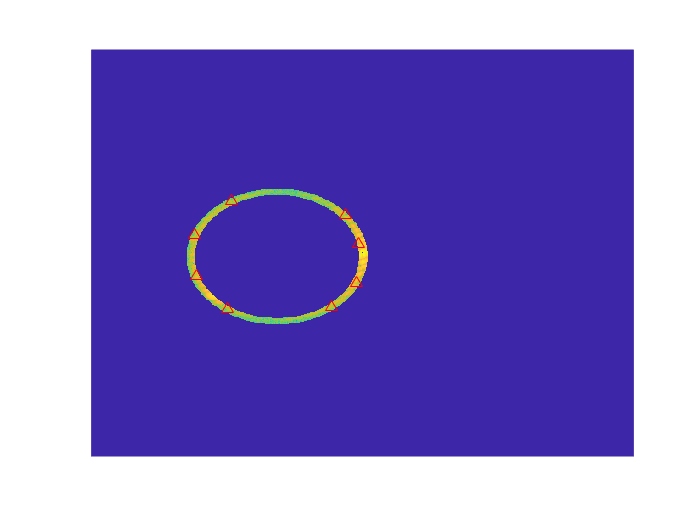

F = fftshift(fft2(ifftshift(I)));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,0);

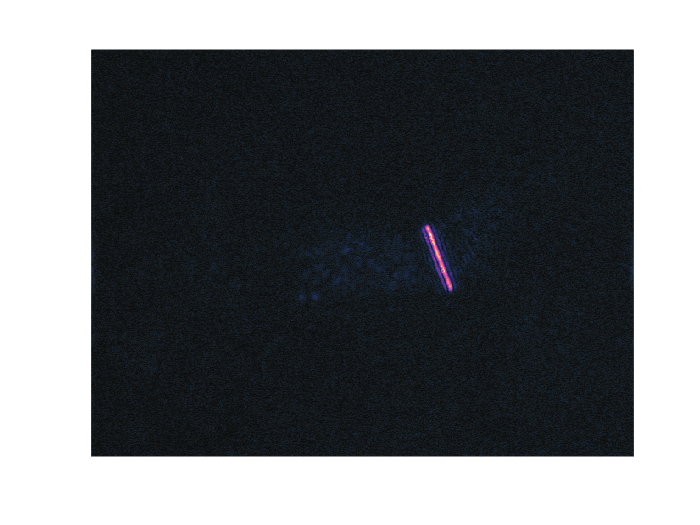

peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.25,'G',2);
I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
figure
imagesc(I_rcn)
axis off
axis equal
colormap(sunglow)

### 截取图片并作图

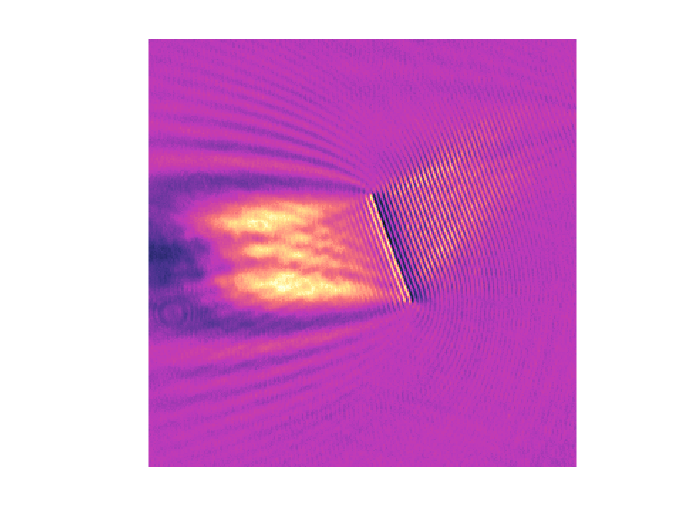

rect = [240 100 300 300];
SPR_cut = imcrop(I,rect);
Rcn_cut = imcrop(I_rcn,rect);
figure
imagesc(SPR_cut)
axis off
axis equal
colormap(sunglow)

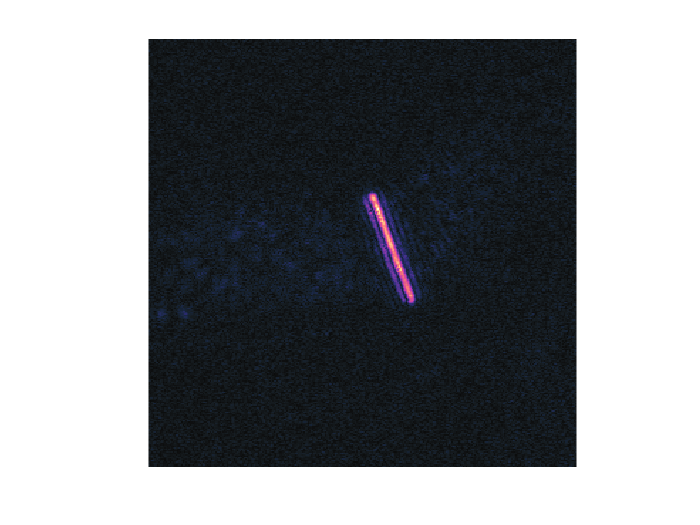

figure
imagesc(Rcn_cut)
axis off
axis equal
colormap(sunglow)

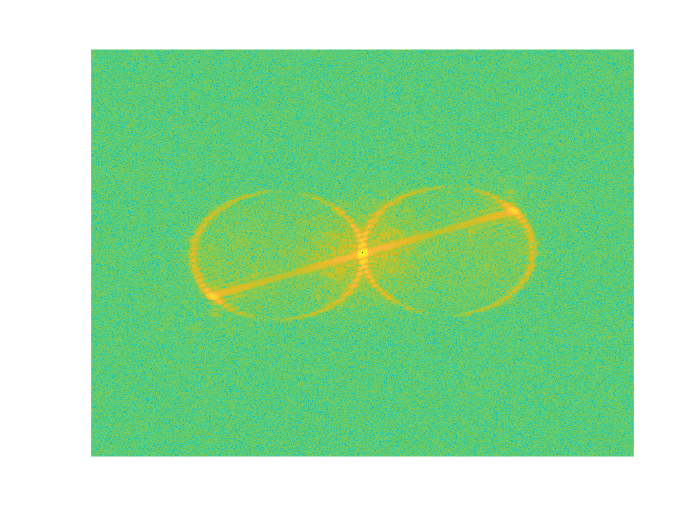

错误使用 ginput (第 84 行)
已被图窗删除操作中断

出错 LineCut (第 16 行)
        [x1,x2] = ginput(2);


% 画剖面得到强度曲线
[int_Rcn,x,y] = LineCut(SPR_cut);

int_SPR = LineCut(Rcn_cut,x,y);
int_SPR = int_SPR/max(int_SPR);
int_Rcn = int_Rcn/max(int_Rcn);

% scalebar
line([65 65+3000/73.8],[253 253],'color','white','linewidth',6)

% 剖面图
f = hypot(diff(x),diff(y))/diff(x);     % x方向每增加一个像素剖面增加的长度
hl = findobj(gca,'type','line');
hl(2).XData = 1:length(int_Rcn);
hl(2).YData = int_Rcn;
hl(1).XData = 1:length(int_SPR);
hl(1).YData = int_SPR;

# **划痕**

### **导入图片并重构**

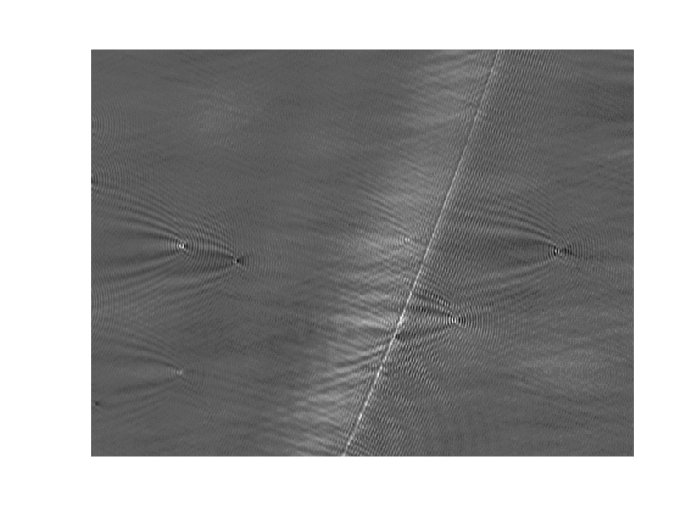

close all
clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220407_AuNPs_AgNWs\AgNWs\scratch';
tiffs = dir(fullfile(tiffpath,'*.tiff'));

BG = MVMExtBG(tiffpath);
I = double(imread(fullfile(tiffpath,tiffs(3).name))) - BG;

figure
imagesc(I);
axis off
axis equal
colormap(gray)

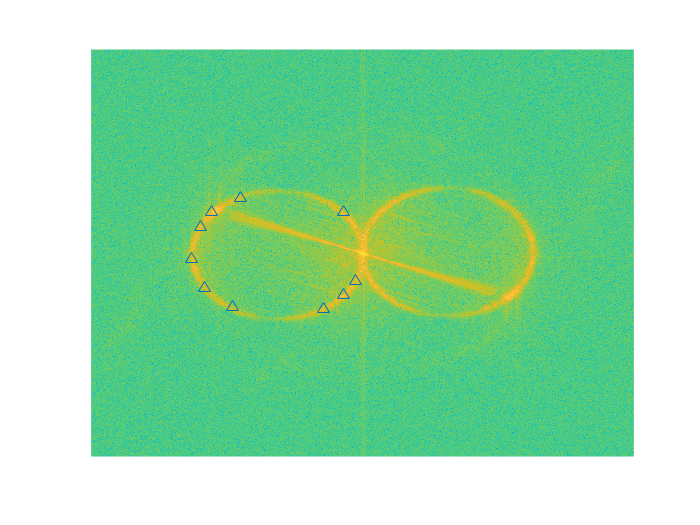

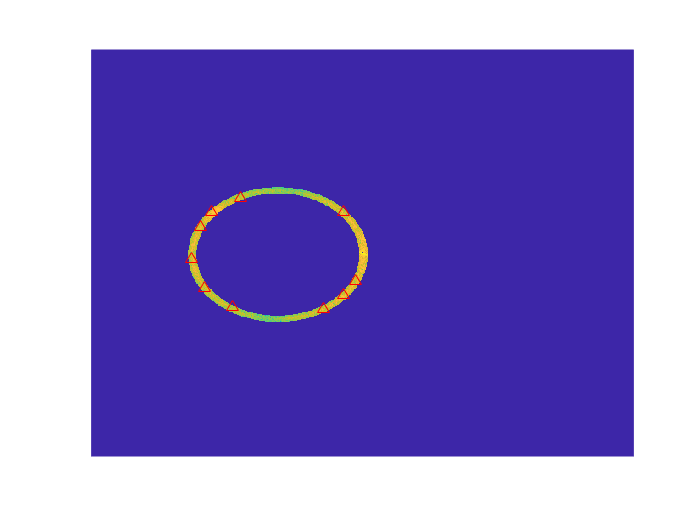


F = fftshift(fft2(ifftshift(I)));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,0);

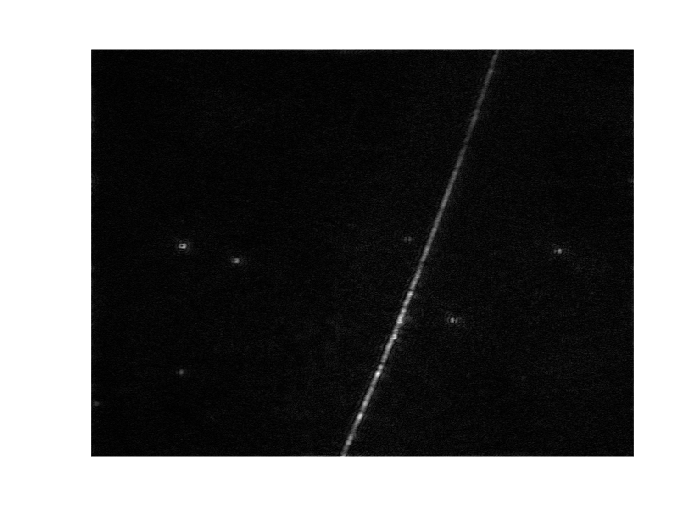

peaks = [center_col,center_raw,R];
mask = EwaldMask(log(abs(F)),peaks,0.25,'G',1);

I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
figure
imagesc(I_rcn)
axis off
axis equal
colormap(gray)

### 截取图片并作图

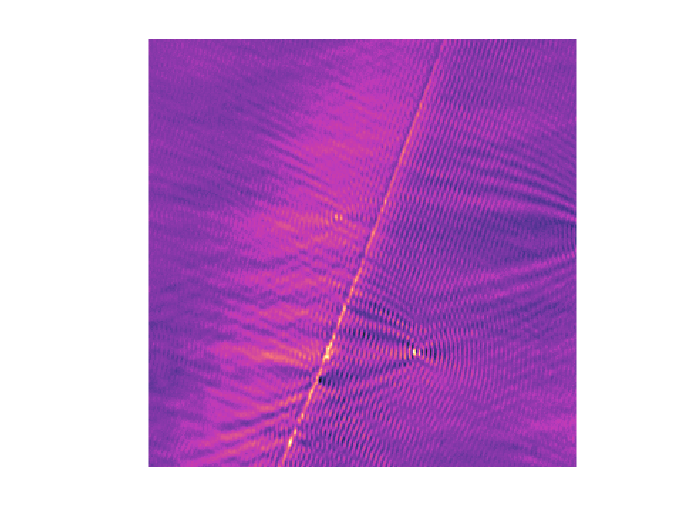

rect = [240 100 300 300];
SPR_cut = imcrop(I,rect);
Rcn_cut = imcrop(I_rcn,rect);
figure
imagesc(SPR_cut)
axis off
axis square
colormap(sunglow)

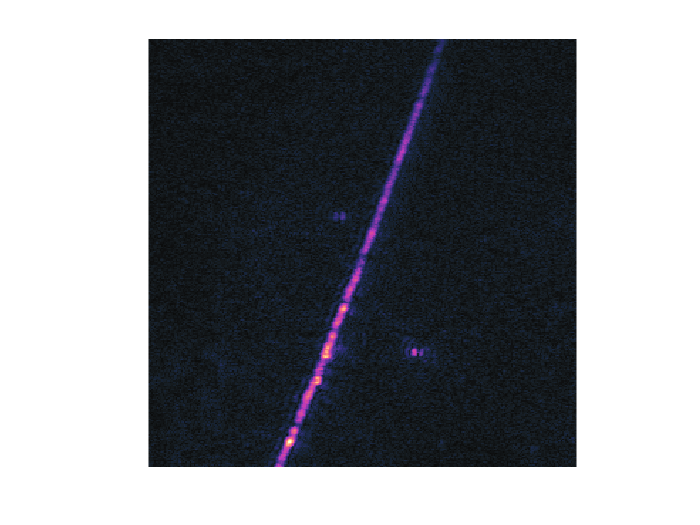

figure
imagesc(Rcn_cut)
axis off
axis square
colormap(sunglow)

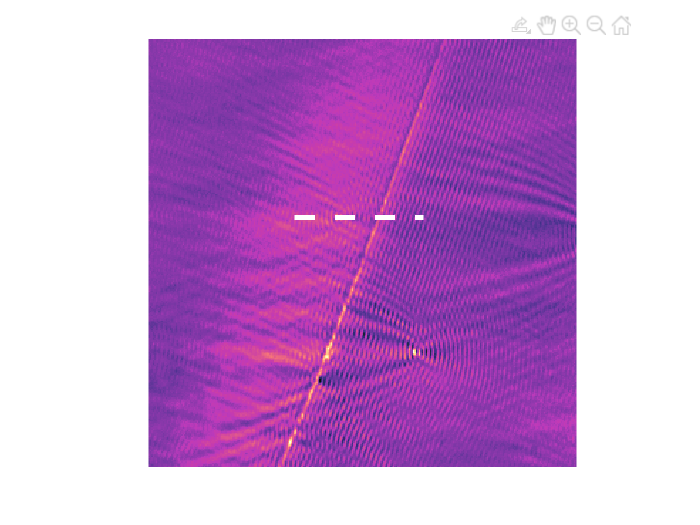

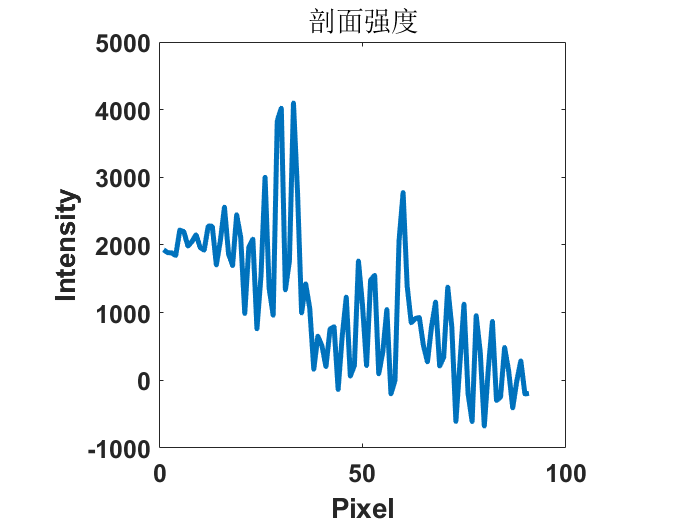


% 画剖面得到强度曲线
[int_Rcn,x,y] = LineCut(SPR_cut);

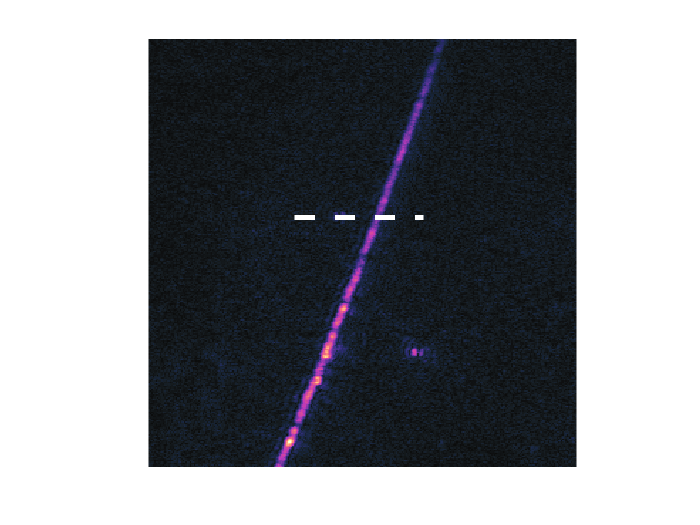

int_SPR = LineCut(Rcn_cut,x,y);

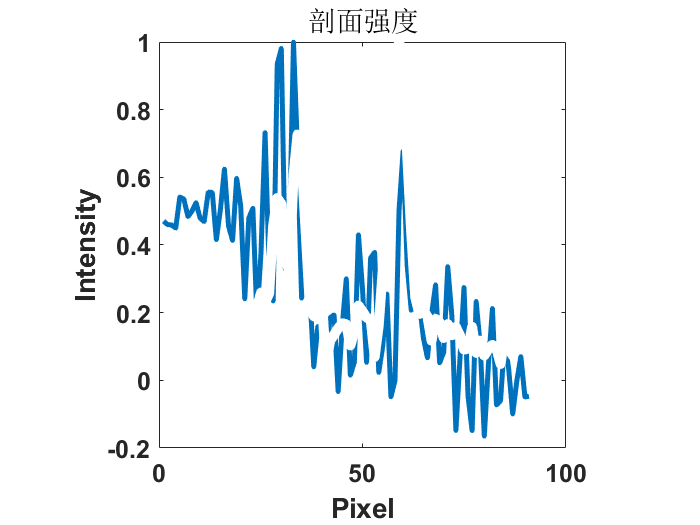

int_SPR = int_SPR/max(int_SPR);
int_Rcn = int_Rcn/max(int_Rcn);

% scalebar
line([65 65+3000/73.8],[253 253],'color','white','linewidth',6)

% 剖面图
f = hypot(diff(x),diff(y))/diff(x);     % x方向每增加一个像素剖面增加的长度
hl = findobj(gca,'type','line');
hl(2).XData = 1:length(int_Rcn);
hl(2).YData = int_Rcn;
hl(1).XData = 1:length(int_SPR);
hl(1).YData = int_SPR;